# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha:**

# Tema 4. Ejercicio 1.1. Identificación de círculos

1) Lee la imagen

RGB = imread('pillsetc.png');
imshow(RGB);

2) Umbraliza la imagen

I = rgb2gray(RGB);
bw = imbinarize(I);
imshow(bw)

3) Elimina el ruido

Usando operaciones morfológicas se eliminan los píxeles que no pertenecen a los objetos de interés.

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill a gap in the pen's cap
se = strel('disk',2);
bw = imclose(bw,se);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

4) Encuentra los contornos

Nos centramos sólo en los límites exteriores. La opción `'noholes' `acelerará el proceso al evitar que la función `bwboundaries` busque contornos internos. 

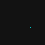

% Obtiene los contornos exteriores de los objetos y la matriz de etiquetas.
% Devuelve:
% - B, los contornos. Es una lista con un elemento por objeto, y cada B{k}
%   es una tabla de puntos [fila, columna] Esos puntos son los píxeles del
%   borde, en el orden en que se recorren al dar la vuelta al objeto. 
% - L, la matriz de etiquetas. Es igual que la imagen, pero cada objeto lleva su número en vez de un 1.
% - n, el número de objetos.
[B,L,n] = bwboundaries(bw,'noholes'); 

% Display the label matrix 
%[0.5, 0.5, 0.5] corresponde a un gris medio para el fondo
imshow(label2rgb(L, @jet, [.5 .5 .5]))

hold on  % to draw the next in the same figure

% draws the boundaries of each object.
for k = 1:n
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Se pide:

- Utilice la ayuda de Matlab para conseguir información sobre la función `regionprops `(parámetros requeridos, propiedades que calcula, etc.).

- Usando dicha función, calcule el área y el perímetro de cada objeto de la imagen previa. 

- A partir del área y el perímetro de cada objeto devueltos por `regionprops`, calcule su circularidad mediante la expresión F=4*pi*A/(p^2) estudiada en teoría. 

- Umbralice el valor de la circularidad y resalte los objetos que sean aproximadamente circulares (p.ej., pintando las boundaries de color diferente). 

- Utilice un slider para comprobar cómo influye el valor del umbral en los objetos seleccionados. 

%% Apartado 1: ayuda de regionprops

% La función regionprops mide propiedades como el área, los centroides... de cada uno de los objetos de una imagen.
% Escribir esto en la ventana de comandos para ver la documentación: doc regionprops

% regionprops(L, 'Propiedad1', 'Propiedad2', ...) recibe una imagen binaria
% o una matriz de etiquetas y devuelve un "struct array": un elemento por
% objeto, con un campo por cada propiedad pedida (Area, Perimeter,
% Centroid, Solidity, ConvexHull, Eccentricity, BoundingBox...).




%% Apartado 2: área y perímetro de cada objeto
% Usamos L (y no bw) para que el objeto k de regionprops sea el mismo
% objeto k que el contorno B{k} de bwboundaries (que regionprops no lo vuelva a numerar).
stats = regionprops(L, 'Area', 'Perimeter', 'Centroid');

% [stats.X] junta en un vector el campo X de todos los objetos
areas = [stats.Area]; % número de píxeles del objeto.
perimetros = [stats.Perimeter]; % longitud del contorno.




%% Apartado 3: circularidad F = 4*pi*A / p^2
% Operador con punto para operar elemento a elemento (calcular F para cada objeto a la vez)
F = 4*pi*areas ./ (perimetros.^2);

% Muestro una tabla con los resultados (el ' transpone)
tablaCirc = table((1:n)', areas', perimetros', F','VariableNames', {'Objeto', 'Area', 'Perimetro', 'Circularidad'})

tablaCirc = 6×4 table
    Objeto    Area     Perimetro    Circularidad
    ______    _____    _________    ____________

      1        8220     320.82         1.0036   
      2         924     104.61          1.061   
      3       17191     524.74        0.78454   
      4         930     105.16         1.0569   
      5        5020     250.16         1.0081   
      6        3133     244.13        0.66058   

	Get insights using Copilot


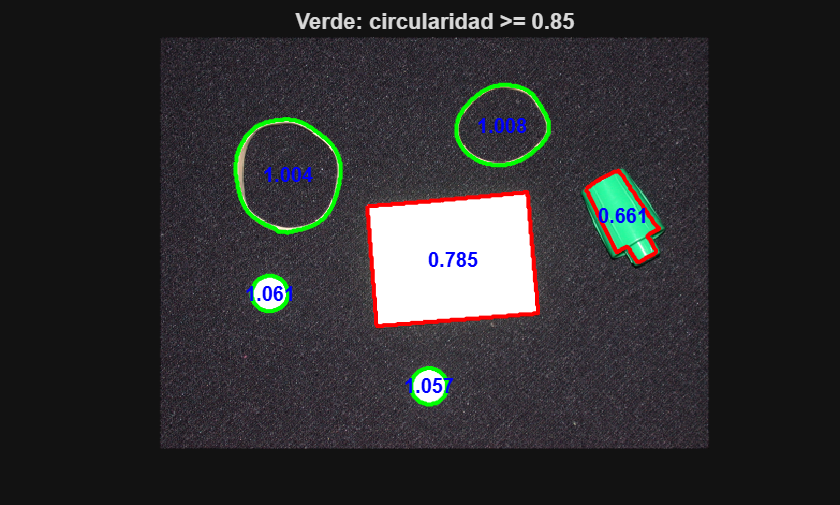





%% Apartados 4 y 5: umbral de circularidad (con slider)
umbralF = 0.85;
figure
imshow(RGB) % imagen original de fondo
hold on 

for k = 1:n
    boundary = B{k}; % contorno del objeto k [fila, col]
    if F(k) >= umbralF
        colorBorde = 'g'; % verde: objeto circular
    else
        colorBorde = 'r'; % rojo: objeto no circular
    end

    % Plot pide puntos tipo (x,y), pero bwboundaries devuelve cada punto
    % como [fila, columna], así que hay que "darle la vuelta"
    plot(boundary(:,2), boundary(:,1), colorBorde, 'LineWidth', 2)

    % Escribo el valor de F en el centro de cada objeto
    c = stats(k).Centroid; % centroide [x, y]
    text(c(1), c(2), sprintf('%.3f', F(k)), 'Color', 'b','FontWeight', 'bold', 'HorizontalAlignment', 'center')
end

hold off
title(['Verde: circularidad >= ', num2str(umbralF)])

La función regionprops mide propiedades de cada uno de los objetos (regiones conexas) de una imagen. Recibe como entrada una imagen binaria o una matriz de etiquetas, seguida de los nombres de las propiedades que se quieren calcular. Devuelve un vector de estructuras con un elemento por objeto y un campo por propiedad. Entre las propiedades disponibles están las de forma (Area, Perimeter, Circularity, Solidity, ConvexArea, ConvexHull, ...), las de posición y tamaño (Centroid, BoundingBox, MajorAxisLength, MinorAxisLength, ...) y, si además se le pasa la imagen de intensidad, propiedades de nivel de gris como MeanIntensity. 

El área es el número de píxeles del objeto. El perímetro lo estima regionprops sumando la distancia entre cada par de píxeles consecutivos del contorno: 1 en los desplazamientos horizontales y verticales y √2 en los diagonales (entorno de vecindad 8). 

La circularidad se ha calculado como F = 4πA/p². Para un círculo ideal F = 1, porque el círculo es la figura que encierra más área para un perímetro dado; cualquier otra forma da (teóricamente) F < 1. 

Los objetos con F mayor o igual que el umbral, controlado por un slider, se resaltan con el contorno en verde y el resto en rojo. El rango del slider se eligió en base a los valores obtenidos para F: el objeto menos circular (el bolígrafo) da unos 0,6, así que el slider comienza en 0,5 (un poco menos). Como algunos valores pasan de 1, termina en 1,1.

Los valores forman dos grupos claramente separados: los objetos no circulares llegan como máximo a 0,785 y los circulares empiezan en 1,004. Cualquier umbral entre 0,79 y 1,00 selecciona correctamente los cuatro objetos circulares. Si el umbral baja de 0,785, el rectángulo se selecciona como circular de forma errónea, y por debajo de 0,661 también el rotulador. Si sube por encima de 1,004, se dejan de seleccionar los objetos circulares grandes. Por ejemplo, con un umbral de 1,01 solo se seleccionan las dos pastillas pequeñas, y solo porque el error de discretización infla su circularidad.

Teóricamente, la circularidad no debería ser mayor a 1: cuanto más cercano a 1, más circular, y 1 es un circulo perfecto. Sin embargo, en la práctica si que se han obtenido valores mayores a 1. Esto se debe a cómo se calcula el perímetro:

Tomemos de ejemplo un cuadrado de 3x3. El recorrido `B{1}` daría 8 pasos de longitud 1, así que calculándolo así el perímetro es 8. El área será de 9 píxeles (3x3). Sin embargo, normalmente un cuadrado de lado 3 tiene perímetro 12 (suma de todos los lados, 3*4 lados), no 8. El camino pasa por el centro de los píxeles del borde, medio píxel por dentro del borde real, así que el perímetro sale más corto. Por eso salen circularidades mayores que 1. En este cuadrado muy pequeño: F = 4π*9 / 8² = 1,77, mientras que si usamos el perímetro de 12 da π/4=0,785 (el resultado teórico correcto). El error es enorme porque el objeto es minúsculo. En objetos grandes, ese medio píxel apenas se nota.

AJUSTAR QUIZAS UN POCO MAS EL SLIDER: CAMBIAR SUS MAX Y MIN MAS PARECIDO A LOS MAX Y MIN QUE SALEN DE LOS VALORES OBTENIDOS

# Tema 4. Ejercicio 1.2. Identificación de objetos cóncavos/convexos

- Cargue la imagen `'Figure1.jpg'` 

- Utilice la función `regionprops` para calcular el área, el área convexa y el índice de convexidad (Solidity). Visualice una tabla con las tres propiedades para todos los objetos de la imagen.

- Resalte la envolvente convexa ('ConvexHull') de cada objeto: en blanco para los objetos cóncavos y en magenta para los convexos, utilizando el valor de `Solidity` para diferenciarlos.

- Utilice un slider para umbralizar el índice de convexidad dentro del rango de valores obtenido (según aparecen en la tabla del punto 2) y compruebe qué objetos son seleccionados al variar el valor del umbral. Justifique si la selección es correcta según los valores obtenidos. 

%% Ejercicio 1.2 - Apartado 1: cargar la imagen
RGB2 = imread('Figure1.jpg');
I2   = rgb2gray(RGB2);

% En esta imagen los objetos son NEGROS sobre fondo BLANCO.
% imbinarize daría el fondo como 1, así que invertimos con ~ (NOT lógico)
bw2 = ~imbinarize(I2);
bw2 = bwareaopen(bw2, 50); % quita puntitos de ruido del JPG (objetos de menos de 50 pixels)
bw2 = imfill(bw2, 'holes'); % rellena posibles agujeros

L2 = bwlabel(bw2); % etiqueta los objetos: 1, 2, 3...
numObj = max(L2(:)); % número de objetos

%% Apartado 2: área, área convexa y Solidity
stats2 = regionprops(L2, 'Area', 'ConvexArea', 'Solidity', 'ConvexHull', 'Centroid');

tablaConv = table((1:numObj)', [stats2.Area]', [stats2.ConvexArea]', [stats2.Solidity]','VariableNames', {'Objeto', 'Area', 'AreaConvexa', 'Solidity'})

tablaConv = 14×4 table
    Objeto    Area     AreaConvexa    Solidity
    ______    _____    ___________    ________

       1       8965        9045       0.99116 
       2       7176        7246       0.99034 
       3       3752        4289        0.8748 
       4      12243       13940       0.87826 
       5       3485        4154       0.83895 
       6       3031        3664       0.82724 
       7       8031        8121       0.98892 
       8       7820        8920       0.87668 
       9       2862        3428       0.83489 
      10      10655       12887        0.8268 
      11       2428        2666       0.91073 
      12       2432        3184       0.76382 
      13       5500        7740       0.71059 
      14       1794        1829       0.98086 

	Get insights using Cop

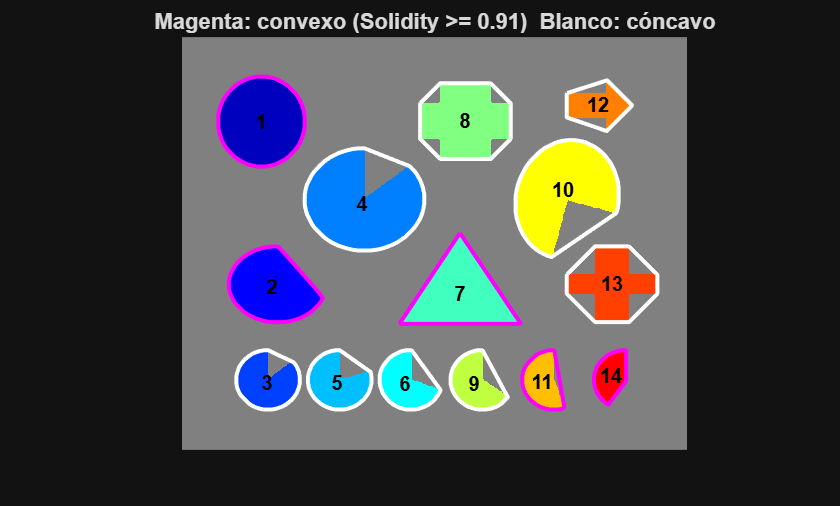

% Se puede comprobar que Solidity o índice de convexidad = Area ./ AreaConvexa

%% Apartados 3 y 4: envolvente convexa coloreada según Solidity (slider)
umbralS = 0.91;
figure
% Fondo gris y objetos de colores, para que se vea el contorno blanco
imshow(label2rgb(L2, @jet, [.5 .5 .5]))
hold on

for k = 1:numObj
    hull = stats2(k).ConvexHull;   % vértices de la envolvente
    
    if stats2(k).Solidity >= umbralS
        colorHull = 'm'; % magenta: convexo
    else
        colorHull = 'w'; % blanco: cóncavo
    end

    % regionprops con ConvexHull devuelve cada punto ya como [x, y], al
    % revés que bwboundaries. No hace falta adaptarlo a lo que pide plot.
    plot(hull(:,1), hull(:,2), colorHull, 'LineWidth', 2)

    % Número del objeto, para poder relacionarlo con la tabla
    c = stats2(k).Centroid;
    text(c(1), c(2), num2str(k), 'Color', 'k', 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center')
end

hold off
title(['Magenta: convexo (Solidity >= ', num2str(umbralS), ')  Blanco: cóncavo'])

La imagen Figure1.jpg contiene objetos negros sobre fondo blanco. Por eso, tras binarizarla con imbinarize se invierte, para que los objetos tengan valor 1. Después se eliminan los objetos de menos de 50 píxeles (ruido de la compresión JPEG), se rellenan los agujeros y se etiquetan los objetos con bwlabel, con lo que se obtienen 14 objetos.

Con regionprops se han calculado el área (A), el área de la envolvente convexa (Ac) y el índice de convexidad Cx = A/Ac, que en MATLAB es la propiedad Solidity. La envolvente convexa es el menor polígono convexo que contiene al objeto. Si el objeto no tiene entrantes, su área coincide prácticamente con la de la envolvente y Cx ≈ 1; cuantos más entrantes tiene, más se aleja Cx de 1. 

Se ha dibujado la envolvente convexa de cada objeto (propiedad ConvexHull) en magenta si el objeto es convexo y en blanco si es cóncavo, según su valor de Solidity y un umbral, controlado con un slider entre 0,70 y 1,00, que cubre el rango de valores de la tabla. El máximo es 1 ya que Solidity nunca puede pasar de este valor: el área del objeto nunca es mayor que la de su envolvente. 

La solidity de los objetos cóncavos llegan hasta ~0,91 y los convexos empiezan en ~0,98, por lo que cualquier valor entre 0,91 y 0,98 separa bien.

Los objetos más convexos (el círculo 1, el círculo cortado por una recta 2, el triángulo 7 y el segmento circular 14) tienen Solidity entre 0.99 y 0,98. No llegan a 1 exactamente por el pixelado del borde. Los objetos cóncavos tienen valores menores: entre 0,827 y 0,878 los comecocos (3, 4, 5, 6, 9 y 10) y la cruz gruesa, y valores aún menores la flecha (0,76) y la cruz delgada (0,71), que son las figuras con entrantes más grandes. El objeto con algo de concavidad con el valor más alto es el 11 (0,91), porque su entrante es muy pequeño.

Por tanto, la selección es correcta para cualquier umbral entre aprox. 0,91 y 0,98. Con un umbral de 0,91, el objeto 11 aparece como convexo. Si el umbral baja más, se van seleccionando como convexos los demás objetos cóncavos, empezando por los de entrantes más pequeños. Si sube por encima de 0,98, se pierden objetos convexos. Esto muestra que Solidity mide cuánta área le falta al objeto respecto a su envolvente, y no si existe o no una concavidad: un objeto con una concavidad muy pequeña puede tener un valor muy próximo al de un objeto convexo.